# ProjectDARIEN: SEIR Epidemiology models

## Description

This script illustrates the use of SEIR Epidemiology models and different features one might observe in them

% Initializing an instance of SEIR model with default values
close all; clear;
instance = SEIRModel; instance = instance.Constructor;
instance.modelType = 'closedSEIR';

instance.N = 100;
currentPopulation = [0.999; 0.001; 0; 0]*instance.N;

eqSEIR = instance.Equilibrium(currentPopulation);

No equilibrium population found: Multiple steady states possible



time = linspace(0, 400, 500)';
SEIR = instance.Dynamic(time, currentPopulation);
%instance.plotDynamic(time, currentPopulation)
R0 = instance.R0

R0 =    2.857142857142857


## Data fitting

This section deals with the data fitting aspect of the model. We start with the sample data generated from above with the columns containing [time, S, E, I, R]

data = [time, SEIR];
instance.modelType = 'closedSEIR'

instance =   SEIRModel with properties:

            N: 100
           mu: 0.005000000000000
         beta: 0.100000000000000
        gamma: 0.035000000000000
            a: 0.100000000000000
           xi: 1.000000000000000e-03
           R0: 2.857142857142857
    modelType: 'closedSEIR'


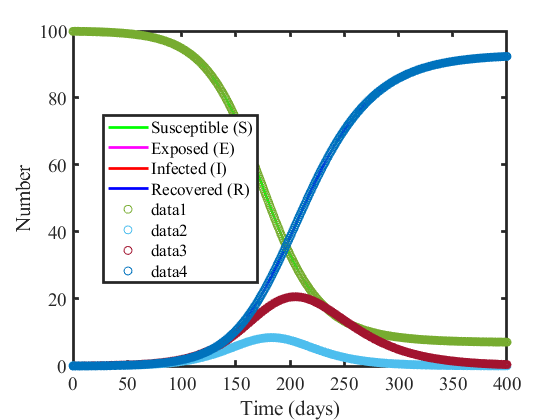

tic;obj = instance.FitData('partemp', data, currentPopulation); toc;
obj.plotDynamic(time, currentPopulation); hold on; plot(data(:,1), data(:,2:end),'o')